# Video Processing: Lab 01

### Task 1

a)

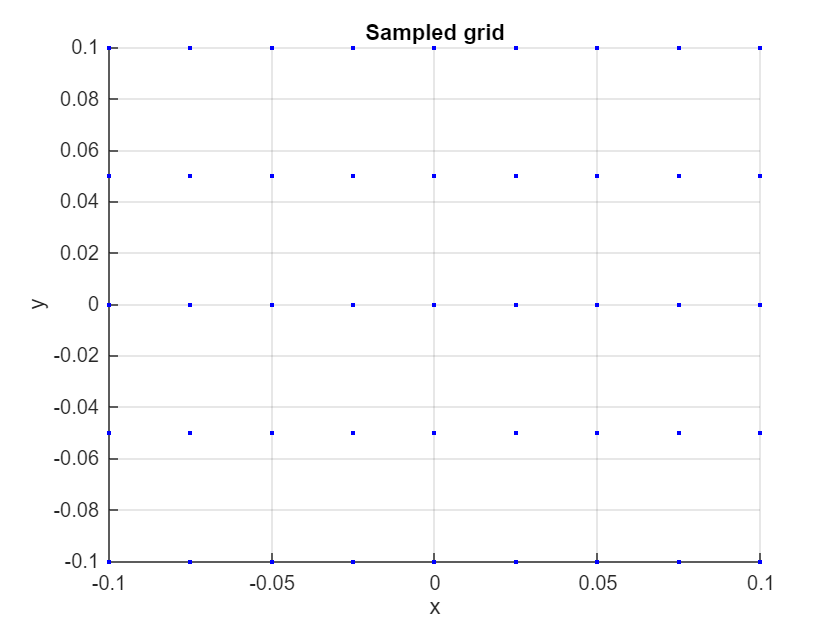

V = [1/40 0; 0 1/20];
function psi = psi(x,y)
    a = 6;
    b = 7;
    psi = cos((5*a + 1)*y) .* cos(10*(5-b)*x) .* sin(5*(a+b)*(x+y));
end

[nx,ny] = meshgrid(-20:20,-20:20);

x = V(1,1)*nx + V(1,2)*ny;
y = V(2,1)*nx + V(2,2)*ny;

figure(1)
scatter(x,y,"blue",".");
title('Sampled grid')
xlabel('x')
ylabel('y')
xlim([-0.1,0.1])
ylim([-0.1,0.1])
grid on

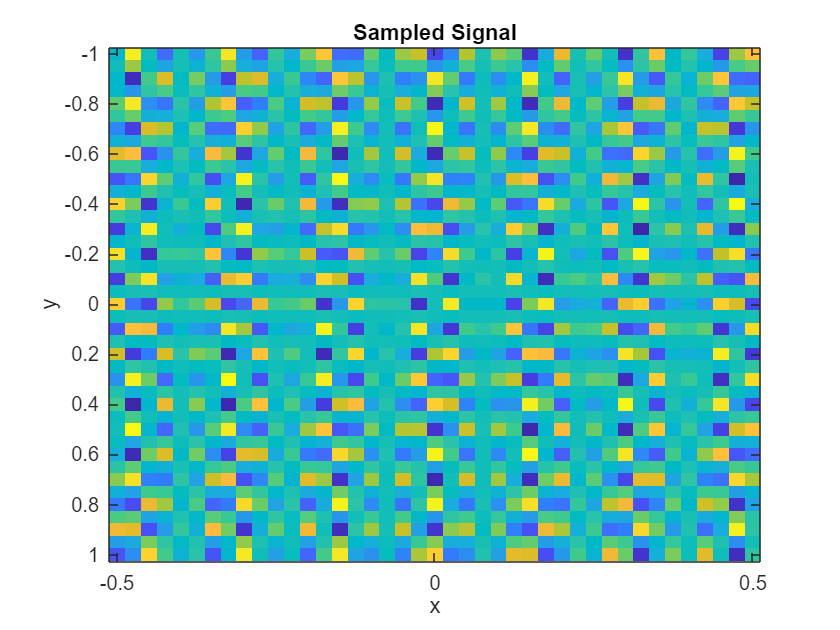



figure(2)
sampled_psi = psi(x,y);
imagesc(x(:),y(:),sampled_psi);
title('Sampled Signal');

xlabel('x');
ylabel('y');

b)

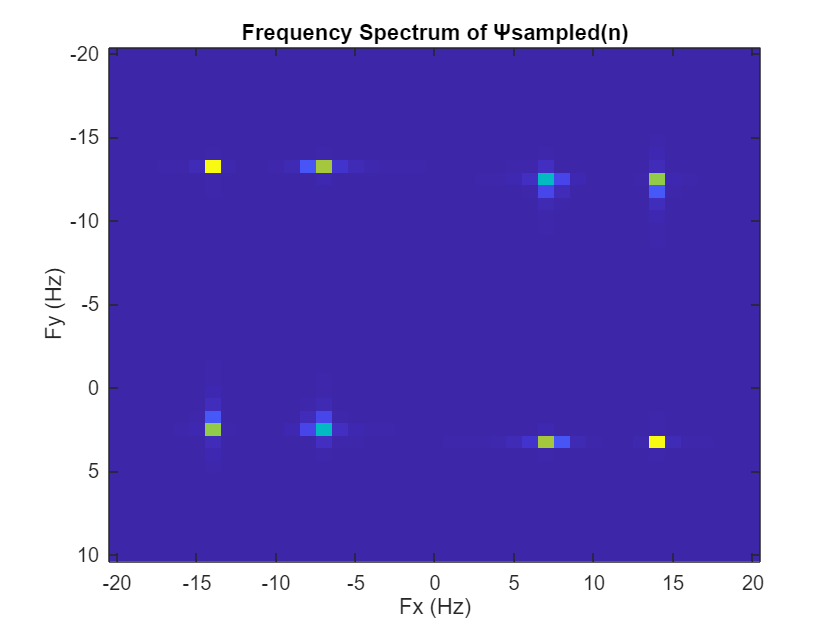

DSFT = fftshift(fft2(sampled_psi)); %calculate the 2D Fourier Transform. 2D because psi depends on both x and y. 
magnitude_DSFT = abs(DSFT).^2; % Calculate the magnitude of the spectrum to separate the phase from the ampltitude (magnitude) for a better visualization (spectral denstity)


[N,M] = size(DSFT);
%N: cantidad de píxeles que tiene la transformada de fourier en eje x
fx = (-floor(N/2):floor(N/2)) / (N-1) *1/(1/40); %1/1/40 -> 40 (frec)
fy = (-floor(M/2):floor(M/2) / (M-1) *1/(1/20)); %1/1/20 -> 20 (frec)

figure(3)
imagesc(fx, fy, magnitude_DSFT);
title('Frequency Spectrum of Ψsampled(n)'); 
xlabel('Fx (Hz)'); 
ylabel('Fy (Hz)'); 
hold on;

c)

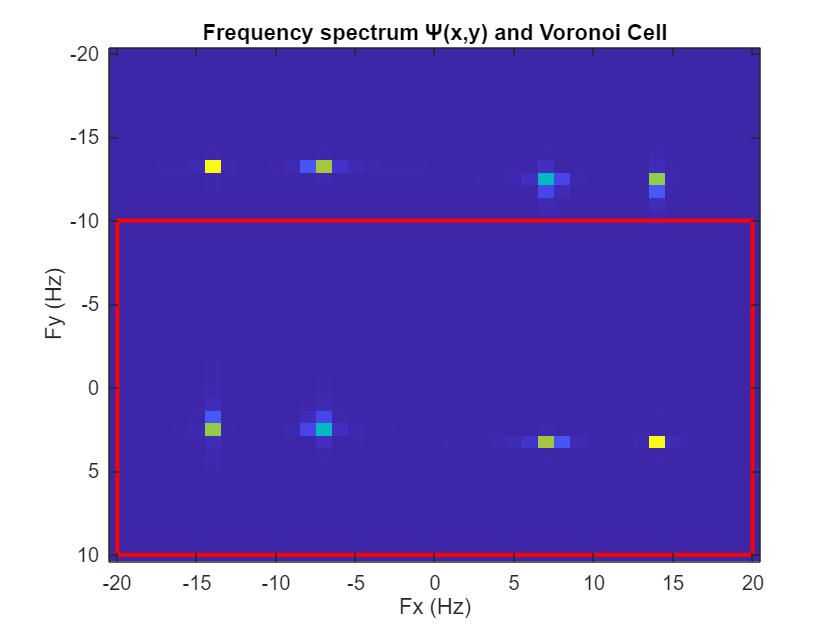

%imagesc(magnitude_DSFT)
U = inv(V.');
midpoints = [U(:,1)/2, -U(:,1)/2, U(:,2)/2, -U(:,2)/2, (U(:,1) + U(:,2))/2, (U(:,1) - U(:,2))/2, (-U(:,1) + U(:,2))/2, (-U(:,1) - U(:,2))/2];


% Extract x and y coordinates
Ux = midpoints(1, :);
Uy = midpoints(2, :);
% Close the shape by connecting points
% Add vertices in the correct order to form a rectangle
vertices_x = [Ux(1), Ux(5), Ux(3), Ux(7), Ux(2), Ux(8), Ux(4), Ux(6),Ux(1)]; % Include the first point again to close the loop
vertices_y = [Uy(1), Uy(5), Uy(3), Uy(7), Uy(2), Uy(8), Uy(4), Uy(6),Uy(1)];

CSFT = fftshift(fft2(psi(x,y))); %calculate the 2D Fourier Transform. 2D because psi depends on both x and y. 
magnitude_CSFT = abs(CSFT).^2; % Calculate the magnitude of the spectrum to separate the phase from the ampltitude (magnitude) for a better visualization (spectral denstity)

% Draw the square-like Voronoi cell
figure(4)
imagesc(fx, fy, magnitude_CSFT);
title('Frequency spectrum Ψ(x,y) and Voronoi Cell'); 
xlabel('Fx (Hz)'); 
ylabel('Fy (Hz)'); 
hold on; %this command ensures that the next plot is on top of the previous ine
plot(vertices_x, vertices_y, '-r', 'LineWidth', 2); % Red lines

#### Task 2

a)

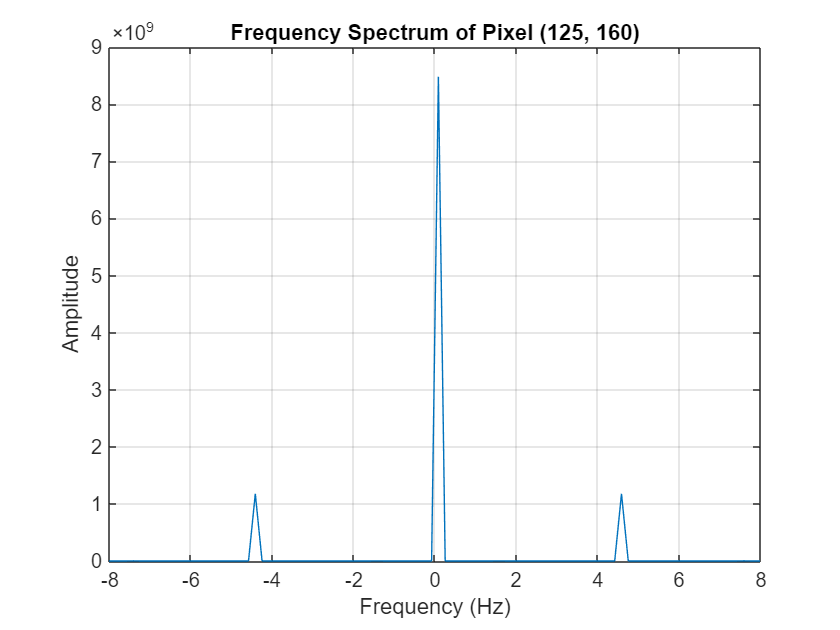

% Read the video
video_obj = VideoReader('VP2025_Lab_1_Task_2.avi');

% Parameters
pixel_x = 125; % Pixel position in x (5 × c)
pixel_y = 160; % Pixel position in y (5 × d)
sampling_rate = 120; % Sampling rate (frames per second)

intensities = zeros(1,video_obj.NumFrames);

for i=1:video_obj.NumFrames
    vidframe = readFrame(video_obj,'native');
    intensities(i) = vidframe.cdata(pixel_y,pixel_x); %stores the pixel intensity for every frame
end 

% Perform FFT
fft_result = fftshift(fft(intensities)); %shift to center it around 0
magnitude = abs(fft_result).^2; %compute the energy
frequencies = ((-floor(video_obj.NumFrames-1)/2):floor(video_obj.NumFrames-1)/2)/6; %signal lasts 6 seconds

% Plot the frequency spectrum
figure(5);
plot(frequencies, magnitude);
title('Frequency Spectrum of Pixel (125, 160)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([-8,8])
grid on;


% Find the maximum frequency component
[max_amplitude, max_index] = findpeaks(magnitude, frequencies, 'SortStr', 'descend', 'NPeaks', 2); %This MATLAB function gives us the value of the frequency axis of the peaks

disp('Frequencies:');

Frequencies:


disp(abs(max_index));

    0.0833    4.4167



c.1) Downsample the video to obtain the video reduced.

video_obj = VideoReader('VP2025_Lab_1_Task_2.avi');
%Chosen frequency is 20 

writer = VideoWriter('videoReduced.avi');
writer.FrameRate = video_obj.FrameRate/6;
open(writer);
for i = 1:video_obj.NumFrames %we are working with the whole video.
    frame = readFrame(video_obj);
    if mod(i,6) == 0 %Ensures only every 6th frame is written to the new video, effectively reducing the frame rate to 20 fps
        writeVideo(writer,frame); %adjusts the frame rate metadata in the output video to match the downsampled rate
    end
end

close(writer)

c.2)

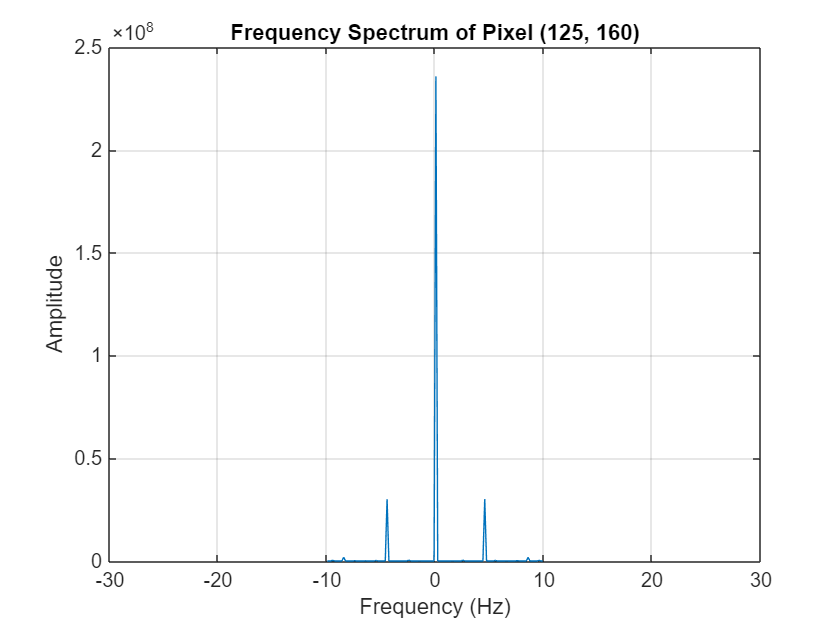

% Load the downsampled video
video_new = VideoReader('videoReduced.avi');

% Parameters
pixel_y=160;
pixel_x=125;
sampling_rate = 20; % New sampling rate
intensities = zeros(1, video_new.NumFrames);

% Extract pixel intensities
for i = 1:video_new.NumFrames
    vidframe = readFrame(video_new,'native'); % Read each frame
    
    % Extract pixel intensity
    intensities(i) = vidframe(pixel_y, pixel_x);
end

% Perform FFT
fft_result = fftshift(fft(intensities)); % Shift to center around 0
magnitude = abs(fft_result).^2; % Compute power spectrum
frequencies = ((-floor(video_new.NumFrames-1)/2):floor(video_new.NumFrames-1)/2)/6 ;

% Plot the frequency spectrum
figure(6);
plot(frequencies, magnitude);
title('Frequency Spectrum of Pixel (125, 160)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([-30, 30]);
grid on;


% Find the maximum frequency component
[max_amplitude, max_index] = findpeaks(magnitude, frequencies, 'SortStr', 'descend', 'NPeaks', 2);

disp('Peak Frequencies:');

Peak Frequencies:


disp(abs(max_index));

    0.0833    4.4167




maxFreq = abs(max_index(1,2)); % The second peak is the highest frequency
disp(['Max Frequency: ', num2str(maxFreq), ' Hz']);

Max Frequency: 4.4167 Hz


d)

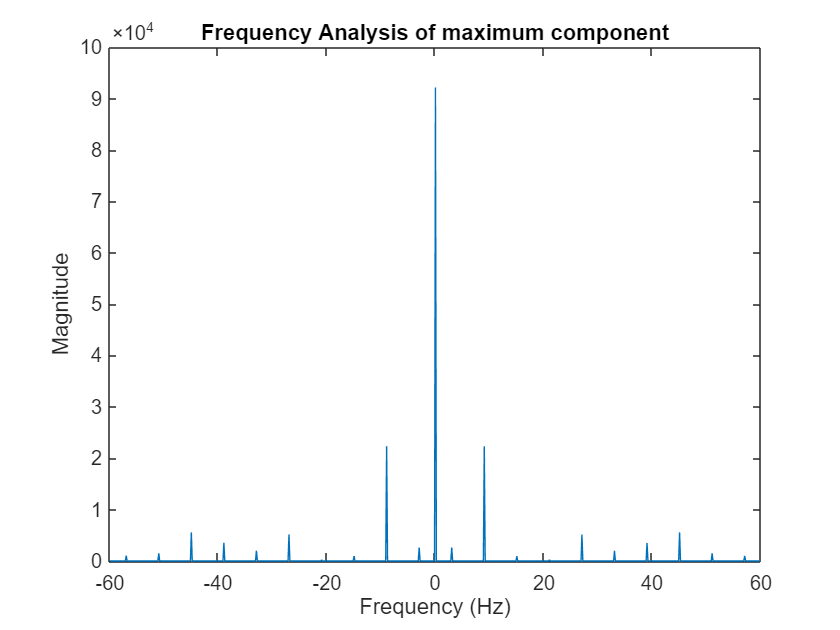

vid = VideoReader('VP2025_Lab_1_Task_2.avi');
matrix_frame = zeros(vid.Height,vid.Width,vid.NumFrames);

for j = 1:vid.NumFrames
    vid_frame = readFrame(vid, 'native');
    for x = 1:vid.Height
        for y = 1:vid.Width
            matrix_frame(x,y,j) = vid_frame.cdata(x, y);
        end
    end
end

% Finding the maximum frequency pixel by pixel:

frec_index = 0; % value to store the index where the f0 is located
intensities = zeros(1,video_obj.NumFrames); %array that stores the intensity of the values for a single pixel

positive_frec = vid.NumFrames/2 + 2; %Starting index of the positive frequencies
for x = 1:vid.Height
    for y = 1:vid.Width
        for i = 1: vid.NumFrames % For each pixel we store all its values along the video
           intensities(i) = matrix_frame(x,y,i); %Extract intensity values of a pixel
        end

        % Magnitude
        transform = abs(fftshift(fft(intensities))); %calculate the FT if a pixel. 
        tempSpectrum = transform(positive_frec:vid.NumFrames); %only considers positive frequencies
        [intensityMax, idx] = max(tempSpectrum); % Find fundamental frequency

        % We keep its spectrum if its fundamental frequency is higher than the ones of the previous pixels
        if idx >= frec_index  
            spectrum = transform; % Store the spectrum of the pixel with the strongest frequency
            max_idx = idx; %update index
        end
    end
end

% Plot the magnitude spectrum
frequencies = ((-floor(video_obj.NumFrames-1)/2):floor(video_obj.NumFrames-1)/2)/6; %signal lasts 6 seconds
figure(7);
plot(frequencies, spectrum); %Only the full spectrum of the pixel with the strongest fundamental frequency index is saved in the spectrum variable.
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Analysis of maximum component');


[max_amplitude, max_index] = findpeaks(spectrum, frequencies, 'SortStr', 'descend', 'NPeaks', 5); %This MATLAB function gives us the value of the frequency axis of the peaks

disp('Peak Frequencies:');

Peak Frequencies:


disp(abs(max_index));

    0.0833    8.9167    9.0833   44.9167   45.0833



d_extended

video_obj = VideoReader('VP2025_Lab_1_Task_2.avi');
%Chosen frequency is 20 (slightly over than 2 . 8,916). That is, 20 samples per second. 

writer = VideoWriter('videotask2d.avi');
writer.FrameRate = video_obj.FrameRate/6;
open(writer);
for i = 1:video_obj.NumFrames %we are working with the whole video.
    frame = readFrame(video_obj);
    if mod(i,6) == 0 %every 6 frames the video is written (120/20).
        writeVideo(writer,frame);
    end
end

close(writer)

e) 

video_obj = VideoReader('VP2025_Lab_1_Task_2.avi');

sampling_rate = 7.2; % aprox freq , 40% of my minimum frequency 8,9*2 = 18
frames_to_keep = floor(video_obj.FrameRate / sampling_rate); % Frames per interval

% Create the new video
writer = VideoWriter('videoAliased.avi');
writer.FrameRate = sampling_rate; % Set the new frame rate to 4 fps
open(writer);

% Downsample the video
for i = 1:video_obj.NumFrames
    frame = readFrame(video_obj,'native'); % Read each frame
    if mod(i, frames_to_keep) == 0 % Keep 1 frame every 'frames_to_keep'
        writeVideo(writer, frame); % Write the frame to the new video
    end
end

close(writer); % Finalize the video
